I = imread('tire.tif');

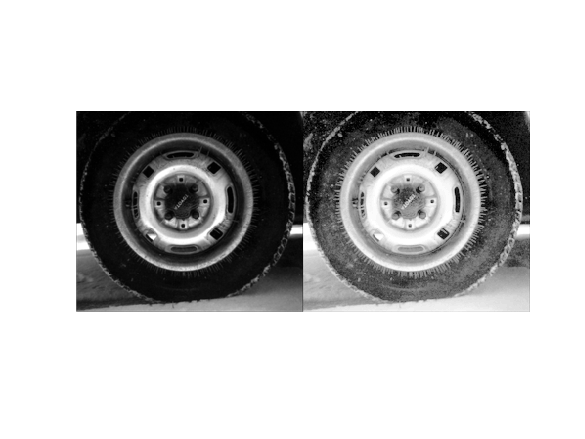

%Enhance the contrast of an intensity image using histogram equalization.
J = histeq(I);
%Display the original image and the adjusted image.
imshowpair(I,J,'montage')
axis off

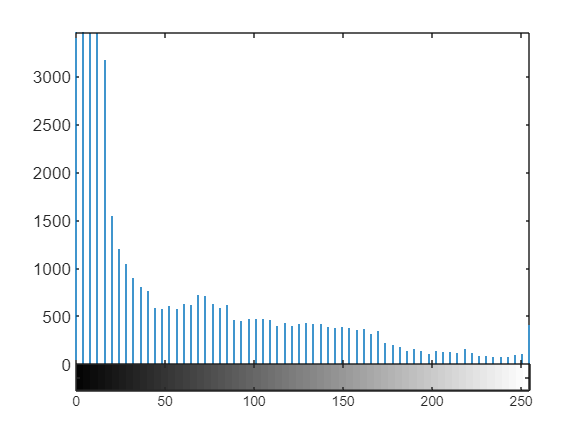

%Display a histogram of the original image.
figure
imhist(I,64)

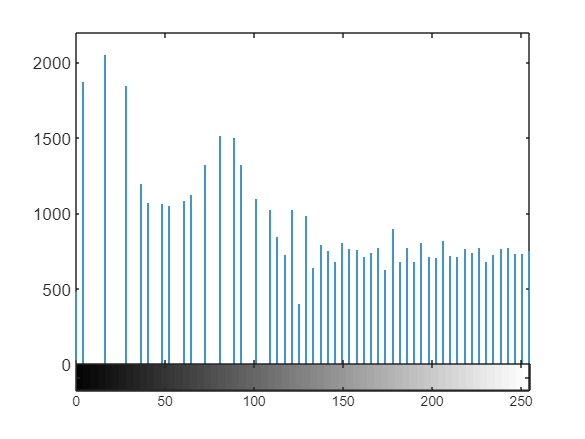

%Display a histogram of the processed image.
figure
imhist(J,64)

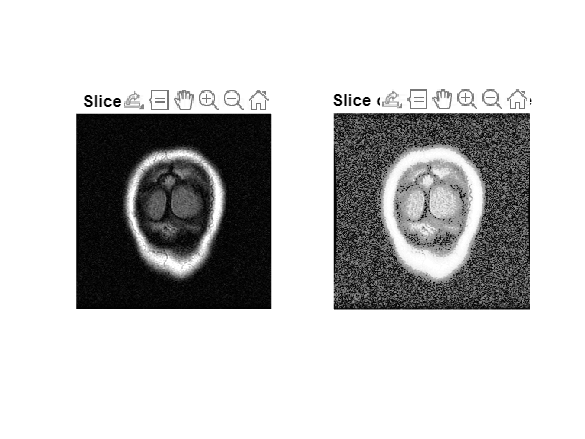

%Load a 3-D dataset.
load mristack
%Perform histogram equalization.
enhanced = histeq(mristack);
%Display the first slice of data for the original image and the contrast-enhanced image.
figure
subplot(1,2,1)
imshow(mristack(:,:,1))
title('Slice of Original Image')
subplot(1,2,2)
imshow(enhanced(:,:,1))
title('Slice of Enhanced Image')

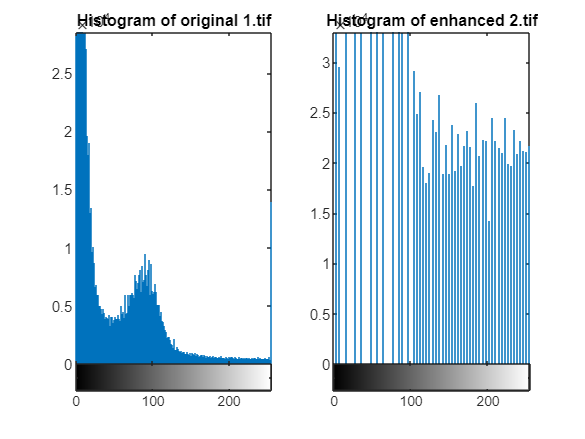

figure
subplot(1,2,1)
imhist(mristack)
title("Histogram of original 1.tif")
subplot(1,2,2)
imhist(enhanced)
title("Histogram of enhanced 2.tif");

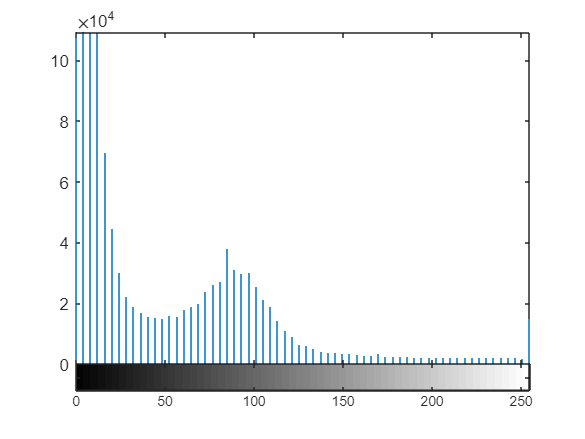

figure
imhist(mristack,64)

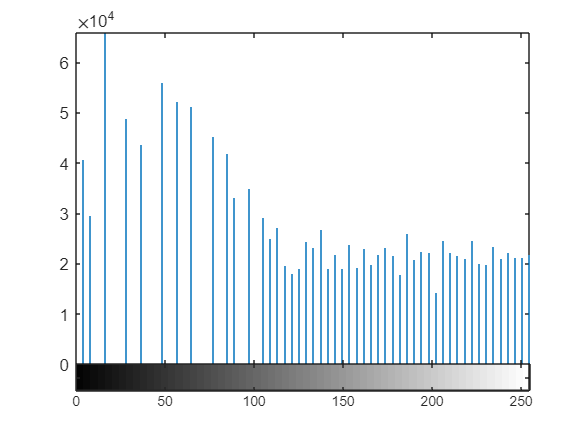

figure
imhist(enhanced,64)

%Enhance the contrast of an intensity image using histogram equalization.
J2 = histeq(I,64);
%Display the original image and the adjusted image.
imshowpair(I,J2,'montage')
axis off

%Display a histogram of the processed image.
figure
imhist(J2,64)

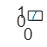

[J3,T] = histeq(I);
figure
plot((0:255)/255,T);

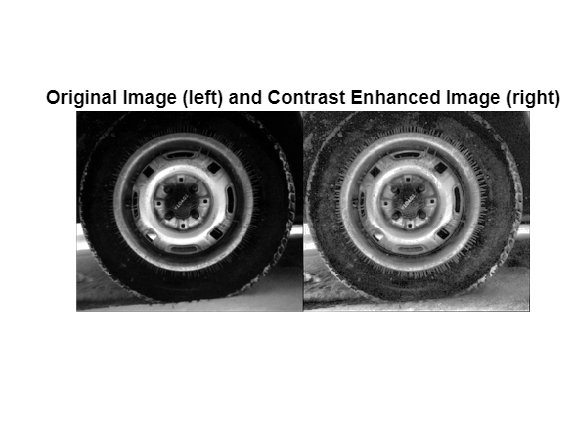

%Apply CLAHE to an image and display the results.
I = imread('tire.tif');
J = adapthisteq(I,'clipLimit',0.02,'Distribution','rayleigh');
imshowpair(I,J,'montage');
title('Original Image (left) and Contrast Enhanced Image (right)')

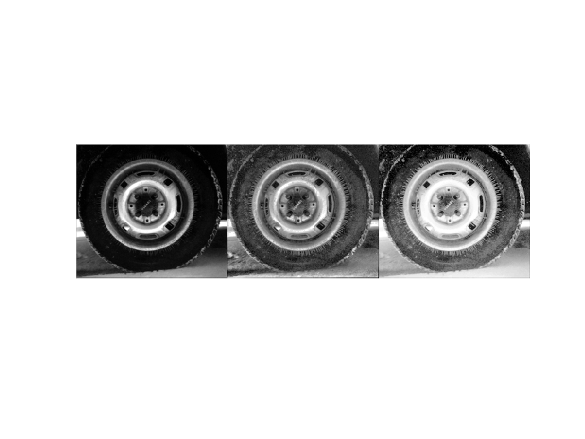

montage({I,J,J2},"Size",[1 3])

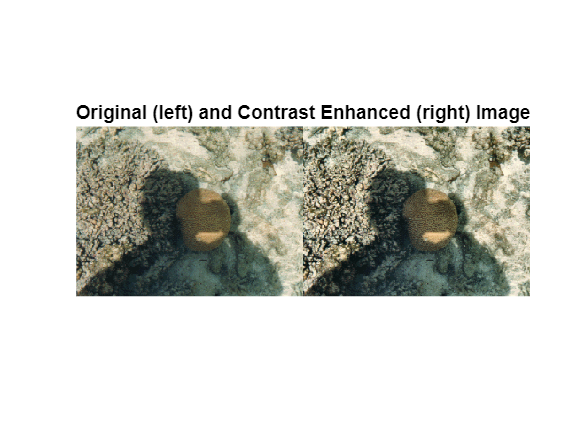

%Read the indexed color image into the workspace.

[X, MAP] = imread('shadow.tif');
%Convert the indexed image into a truecolor (RGB) image, then convert the RGB image into the L*a*b* color space.

RGB = ind2rgb(X,MAP);
LAB = rgb2lab(RGB);
%Scale values to the range expected by the adapthisteq function, [0 1].

L = LAB(:,:,1)/100;
%Perform CLAHE on the L channel. Scale the result to get back to the range used by the L*a*b* color space.
L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
LAB(:,:,1) = L*100;
%Convert the resulting image back into the RGB color space.
J = lab2rgb(LAB);
%Display the original image and the processed image.
figure
imshowpair(RGB,J,'montage')
title('Original (left) and Contrast Enhanced (right) Image')